# 题目8：HSI空间仅平滑I分量

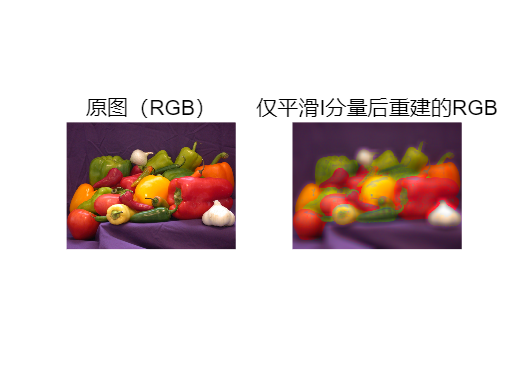

% 读取图像并转换为double类型
img_rgb = imread('peppers.png'); % 替换为你的图像路径
img_rgb = im2double(img_rgb);

% 步骤1：将RGB转换为HSI
R = img_rgb(:,:,1); G = img_rgb(:,:,2); B = img_rgb(:,:,3);
I = (R + G + B) / 3; % 亮度分量

minRGB = min(img_rgb, [], 3);
S = 1 - minRGB ./ (I + eps); % 饱和度分量
S(I == 0) = 0; % 处理I=0的情况

theta = acos( (2*R - G - B) ./ (2*sqrt((R-G).^2 + (R-B).*(G-B)) + eps ));
H = theta;
H(B > G) = 2*pi - H(B > G); % 调整色相范围到[0, 2π]
H = H / (2*pi); % 归一化到[0,1]

% 步骤2：对I分量进行25×25均值滤波
I_smooth = imfilter(I, fspecial('average', 25), 'replicate');

% 步骤3：将HSI转回RGB
H_recon = H * 2 * pi; % 恢复为[0, 2π]
S_recon = S;
I_recon = I_smooth;

% 预分配RGB矩阵
rows = size(H_recon, 1); cols = size(H_recon, 2);
R_recon = zeros(rows, cols);
G_recon = zeros(rows, cols);
B_recon = zeros(rows, cols);

% 分区域计算RGB
for i = 1:rows
    for j = 1:cols
        h = H_recon(i,j);
        s = S_recon(i,j);
        i_val = I_recon(i,j);
        
        % 判断色相区域
        if h >= 0 && h < 2*pi/3
            % 区域1：0°-120°（红-黄-绿）
            x = i_val * (1 - s);
            y = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            z = 3*i_val - (x + y);
            R_recon(i,j) = y;
            G_recon(i,j) = z;
            B_recon(i,j) = x;
        elseif h >= 2*pi/3 && h < 4*pi/3
            % 区域2：120°-240°（绿-青-蓝）
            h = h - 2*pi/3;
            x = i_val * (1 - s);
            y = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            z = 3*i_val - (x + y);
            R_recon(i,j) = x;
            G_recon(i,j) = y;
            B_recon(i,j) = z;
        else
            % 区域3：240°-360°（蓝-品红-红）
            h = h - 4*pi/3;
            x = i_val * (1 - s);
            y = i_val * (1 + s*cos(h)/cos(pi/3 - h));
            z = 3*i_val - (x + y);
            R_recon(i,j) = z;
            G_recon(i,j) = x;
            B_recon(i,j) = y;
        end
    end
end

% 合并RGB并限制范围
img_recon_smooth = cat(3, R_recon, G_recon, B_recon);
img_recon_smooth = max(min(img_recon_smooth, 1), 0);

% 显示结果
figure;
subplot(1,2,1), imshow(img_rgb), title('原图（RGB）');
subplot(1,2,2), imshow(img_recon_smooth), title('仅平滑I分量后重建的RGB');